# **Data Averaging**

Rabi, Ramsey, Spin echo, Cat ratio    

## Data Input 


close all;
clear all;
colors=npg(10); % Ten basic colors 
maindir='\\Artemis-pc\e\Data\2024-12-31\Abs-1206\';
main_dir_0=maindir;
load([maindir,'\population.mat']);
%load([maindir,'\result.mat']);
%load([maindir,'\negative_mag.mat']);


### 第一条曲线

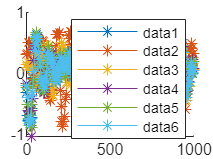

close all;

% x_label='Pulse Length us';
% x_label='556 Freq ( \Gamma )';
% x_label='556 FM V';
% x_label='399 FM V';
x_label='Precession (ms)';
% x_label='399 Freq MHz';
% x_label = 'Hold Time s';
% x_label = 'MOT Load s';

y_lim_low=-1;
y_lim_high=1;

xlist = 0:5:1000;
%xlist=[1 5 10 25 50 100 200 400 800 1600];
%xlist=[0.2 1 2 3 5:5:50];
%xlist=([0.16:0.005:0.54]-0.2273).*100;

x_lim_low=min(xlist);
x_lim_high=max(xlist);

%relativeOD = (s1+s2);
%relativeOD = [s11',s1'];
%relativeOD = s2./(s3+s2);
%relativeOD = s1./s2;
%relativeOD = s2./s1;
%relativeOD = (s1+s2)./s5;
relativeOD = (s1-s2)./(s1+s2);

repeat_se = length(relativeOD)/length(xlist);
reshape_phase=reshape(relativeOD,length(xlist),repeat_se);


figure;hold on;
for i=1:repeat_se
    plot(xlist,reshape_phase(:,i),'*-');
end
legend;
hold off;

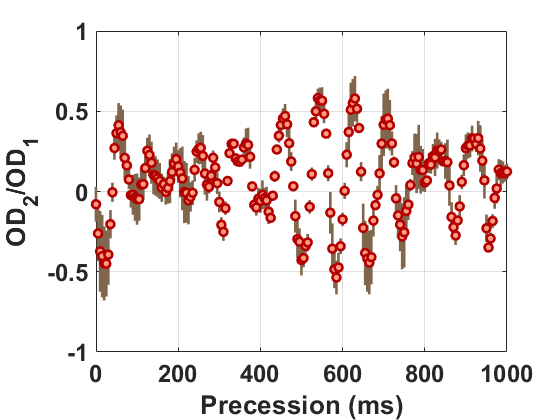


% reshape_phase(:,1:3)=[];
% reshape_phase(:,24:27)=[];
% reshape_phase(:,21)=[];
% reshape_phase(:,7)=[];
% reshape_phase(:,2)=[];
% reshape_phase(:,4)=[];
% reshape_phase(:,3)=[];

%reshape_phase=reshape(relativeOD,length(xlist),repeat_se)./2+0.5;
%reshape_phase=reshape(relativeOD_2,length(xlist),repeat_se);
%reshape_phase=reshape(relativeOD,length(xlist),repeat_se)/2+1/2;


h1=figure;

%yyaxis right;

if repeat_se > 1

    phase_mean=mean(reshape_phase');
    phase_std=std(reshape_phase');

    phase_weight=1./phase_std.^2;

    phase_mean = phase_mean;

    %I_se=errorbar(xlist,phase_mean./1,phase_std/sqrt(9),'o');
    I_se=errorbar(xlist,phase_mean./1,1.*phase_std/sqrt(repeat_se-1),'o');
    %I_se=errorbar(x_mean,phase_mean,phase_std/sqrt(repeat_se-1),...
    %    phase_std/sqrt(repeat_se-1),x_std/sqrt(repeat_se-1),...
    %    x_std/sqrt(repeat_se-1),'o');
    %I_se=errorbar(xlist,phase_mean./max(phase_mean),phase_std/sqrt(repeat_se-1)./max(phase_mean),'o');

    I_se.CapSize=0;
    I_se.MarkerSize=50;
    I_se.LineWidth=2;
    I_se.Color=[0.5,0.4,0.3];
    I_se.MarkerSize=6;
    I_se.MarkerEdgeColor=[0.7 0 0];
    I_se.MarkerFaceColor=[1 0.6 0.5];

elseif repeat_se == 1
    plot(xlist,reshape_phase,'.','Color',[0.7 0 0],'MarkerSize',20);
    %plot(xlist,reshape_phase./max(reshape_phase),'.','Color',[0.7 0 0],'MarkerSize',20);
end

xlabel(x_label)
%ylabel('OD_1/OD_2');
ylabel('OD_2/OD_1');
%ylabel('OD_1');
%ylabel('S_z');
%ylabel('Relative OD');
%ylabel('Ratio of +1/2');
%ylabel('Ratio of +5/2');
%ylabel('Cat Ratio');

grid on;
box on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold');
xlim([x_lim_low x_lim_high]);
ylim([y_lim_low y_lim_high]);
%ylim([-1 1]);
% line([x_lim_low x_lim_high],[0 0],'Color',[0.5,0.5,0.5]);

%set(gca,'XScale','log');
%set(gca,'YScale','log');

set(gcf,'Visible','on');


%datatip(I_se);
%xticks([]);


### 第二条曲线


%hold on;
yyaxis left;

错误使用 matlab.graphics.axis.Axes/addDataSpace
运算被用户终止。

出错 yyaxis

出错 yyaxis


relativeOD2 = s2;

repeat_se = length(relativeOD)/length(xlist);
reshape_phase2=reshape(relativeOD2,length(xlist),repeat_se);

% figure;hold on;
% for i=1:repeat_se
%     plot(xlist,reshape_phase2(:,i),'*-');
% end
% legend;
% hold off;

%reshape_phase2(:,4)=[];
%reshape_phase2(:,3)=[];

phase_mean2=mean(reshape_phase2,2);
phase_std2=std(reshape_phase2,0,2);

phase_weight2=1./phase_std2.^2;

I_se2=errorbar(xlist,phase_mean2./1,1.*phase_std2/sqrt(repeat_se-1),'o');

I_se2.CapSize=0;
I_se2.MarkerSize=50;
I_se2.LineWidth=2;
I_se2.Color=[0.45,0.63,0.67];
I_se2.MarkerSize=6;
I_se2.MarkerEdgeColor=[0.04,0.59,0.83];
I_se2.MarkerFaceColor=[0.29,0.91,0.91];

%legend('OD_2/OD_1','OD_1');

ylabel('OD_2');
ylim([100 400]);
set(gca,'YScale','linear');

%xticks([10^1 10^2 10^3 10^4 10^5]);
grid on;
box on;

legend('OD_1/OD_2','OD_2','Location','best');

set(gcf,'Visible','on');


### Save


savefig(h1,[main_dir_0,'\Aver173.fig']);
saveas(h1,[main_dir_0,'\Aver173.png']);


save([main_dir_0,'\aver173.mat']);


savefig(h1,[main_dir_0,'\Aver171.fig']);
saveas(h1,[main_dir_0,'\Aver171.png']);

save([main_dir_0,'\aver171.mat']);


## **2D PLOT**

% Plot 2D %


first_para =  0.8:0.1:1.5;
second_para = [5 10:10:100];


xlabel_2D= 'Lattice Power AM V'; % first_para
ylabel_2D='Probe Pulse us'; % second_para


### OD2 / OD1


relativeODnormalize = s2./s1;
repeat_se = length(relativeODnormalize)/(length(first_para)*length(second_para));
reshape_ODnormalize=reshape(relativeODnormalize,length(first_para)*length(second_para),repeat_se);


ODnormalize_mean = sum(reshape_ODnormalize,2)/repeat_se;


data_2D_normalize=reshape(ODnormalize_mean,length(second_para),length(first_para));% 数据竖列重排


fig2d=figure
b = bar3(data_2D_normalize,1);
colorbar

for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end

axis([])
xlim([1-0.5,length(first_para)+0.5])
ylim([1-0.5,length(second_para)+0.5])
clim([0.8 1]);
xticks([1:length(first_para)])
yticks([1:length(second_para)])
set(gca,'XTickLabel',first_para)
set(gca,'YTickLabel',second_para)
xlabel(xlabel_2D)
ylabel(ylabel_2D)

title('OD2/OD1');

view([0 90])
saveas(fig2d,[maindir,'Abs-',num2str(last),'\AverNormalize2D.fig'])
saveas(fig2d,[maindir,'Abs-',num2str(last),'\AverNormalize2D.png'])


### OD2


relativeOD = s2;
repeat_se = length(relativeOD)/(length(first_para)*length(second_para));
reshape_OD=reshape(relativeOD,length(first_para)*length(second_para),repeat_se);


OD_mean = sum(reshape_OD,2)/repeat_se;


data_2D=reshape(OD_mean,length(second_para),length(first_para));% 数据竖列重排


fig2d=figure
b = bar3(data_2D,1);
colorbar

for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end

axis([])
xlim([1-0.5,length(first_para)+0.5])
ylim([1-0.5,length(second_para)+0.5])
clim([0 20])

xticks([1:length(first_para)])
yticks([1:length(second_para)])
set(gca,'XTickLabel',first_para)
set(gca,'YTickLabel',second_para)
xlabel(xlabel_2D)
ylabel(ylabel_2D)

title('OD2');

view([0 90])
saveas(fig2d,[maindir,'Abs-',num2str(last),'\Aver2D.fig'])
saveas(fig2d,[maindir,'Abs-',num2str(last),'\Aver2D.png'])



### OD1


relativeOD = s1;
repeat_se = length(relativeOD)/(length(first_para)*length(second_para));
reshape_OD=reshape(relativeOD,length(first_para)*length(second_para),repeat_se);
re_OD_mean = sum(reshape_OD,2)/repeat_se;
re_OD=reshape(re_OD_mean,length(second_para),length(first_para));


OD_mean=mean(re_OD);
OD_std=std(re_OD);


h10 = figure;

I_se=errorbar(first_para,OD_mean./1,1.*OD_std/sqrt(repeat_se*length(second_para)-1),'o-');


x_lim_low=min(first_para);
x_lim_high=max(first_para);

xlabel(xlabel_2D)
ylabel('OD 1')
set(gca,'FontSize',18)
xlim([x_lim_low x_lim_high]);
line([x_lim_low x_lim_high],[0 0],'Color',[0.5,0.5,0.5])

I_se.CapSize=0;
I_se.MarkerSize=50;
I_se.LineWidth=2;
I_se.Color=[0.5,0.4,0.3];
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=[0.7 0 0];
I_se.MarkerFaceColor=[1 0.6 0.5];
%set(gca,'XScale','log')
%set(gca,'YScale','log')

saveas(h10,[main_dir_0,'\AverOD1.fig'])
saveas(h10,[main_dir_0,'\AverOD1.png'])
save([main_dir_0,'\average.mat'])



## **Count Per Pixel**

relativeOD = countperpixel
%relativeOD = s2./s1;
repeat_se = length(relativeOD)/length(xlist);
countperpixel_phase=reshape(countperpixel,length(xlist),repeat_se);
countperpixel_mean=mean(countperpixel_phase');
countperpixel_std=std(countperpixel_phase');


I_se=errorbar(countperpixel_mean,phase_mean./1,1.*phase_std/sqrt(length(phase_std)),1.*phase_std/sqrt(length(phase_std)),countperpixel_std,countperpixel_std,'o-');
xlabel(x_label)
ylabel('OD 2/OD 1')
ylabel('Survival')
set(gca,'FontSize',18)
xlim([0 2200])
ylim([0.8 1])
line([0 2200],[0 0],'Color',[0.5,0.5,0.5])

I_se.CapSize=0;
I_se.MarkerSize=50;
I_se.LineWidth=2;
I_se.Color=[0.5,0.4,0.3];
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=[0.7 0 0];
I_se.MarkerFaceColor=[1 0.6 0.5];
set(gca,'YScale','linear')

I_se=errorbar(phase_mean3,phase_mean./1,1.*phase_std/sqrt(length(phase_std)),'o-')
hold on


## **Phase Uncertainty**

close all;

x_label='precession s';
x_lim_low=0;
x_lim_high=110;
y_lim_low=-1;
y_lim_high=1.0;

%xlist=(0:20:2000)./1000;
precession=[1 10 20 40 60 80 100];
repeat_se = length(relativeOD)/length(precession);
reshape_phase=reshape(relativeOD,repeat_se,length(precession));

figure;hold on;
for i=1:length(precession)
    plot(1:repeat_se,reshape_phase(:,i));
end
legend;


%reshape_phase=reshape(relativeOD,length(xlist),repeat_se)./2+0.5;
%reshape_phase=reshape(relativeOD_2,length(xlist),repeat_se);
%reshape_phase=reshape(relativeOD,length(xlist),repeat_se)/2+1/2;

reshape_phase(1:40,:) = [];

phase_mean=mean(reshape_phase);
phase_std=std(reshape_phase);

phase_weight=1./phase_std.^2;
h1=figure
I_se=errorbar(precession,phase_mean,phase_std,'o');

I_se.CapSize=0;
I_se.MarkerSize=50;
I_se.LineWidth=2;

xlabel(x_label)
ylabel('Sz')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])

I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')

saveas(h1,[main_dir_0,'\Contrast.png'])
save([main_dir_0,'\average.mat'])


n_atom = numberofatoms1+numberofatoms2;
reshape_n = reshape(n_atom,repeat_se,length(precession));
reshape_n(1:40,:) = [];

% for i = 1:length(precession)
%     atom_num(i) = 



## Ramsey

x_label='Ramsey interrogation time ms';
%x_label='2\tau s';
x_lim_low=0;
x_lim_high=0.03;
y_lim_low=0;
y_lim_high=1.0;

relativeOD=s1./s2;

xlist=(0:7:210)+6;
xlist=(0:0.01:4)+0.012;
xlist=(0.001:0.001:0.03)+0.006;
xlist=(10:10:200);
precession1=[0.01 1 5 10 25 50];
repeat_se = length(relativeOD)/length(xlist)/length(precession1);
reshape_phase=reshape(relativeOD,length(xlist),repeat_se,length(precession1));

reshape_phase(:,1:3,:)=[];repeat_se=repeat_se-3;

phase_mean=mean(reshape_phase,2);
phase_std=std(reshape_phase,1,2);
phase_weight=1./phase_std.^2;

for j=1:length(precession1)
h2=figure
I_se=errorbar(xlist,phase_mean(:,1,j),phase_std(:,1,j)./sqrt(repeat_se-1),'o');

xlabel(x_label)
ylabel('+5/2')
set(gca,'FontSize',16)
%xlim([x_lim_low x_lim_high])
%ylim([y_lim_low y_lim_high])

title([num2str(precession1(j)),'s'])

I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
end

saveas(h2,[main_dir_0,'\Contrast.png']);
save([main_dir_0,'\average.mat']);


## Cat Ratio


x_label='Precession s';

x1 = [0.2 2.2 4 8 10 12 20 40 50];
xlist = 0:5:200;

x_lim_low = 0;
x_lim_high = max(x1)*1.05;
y_lim_low = 0;
y_lim_high = 2;

ratio = (s1+s2)./s3;

repeat_se = length(ratio)/length(x1)/length(xlist);
reshape_phase = reshape(ratio,length(xlist),repeat_se,length(x1));


phase_mean = mean(reshape_phase,2);
phase_std = std(reshape_phase,1,2);
phase_weight = 1./phase_std.^2;



for k = 1:length(xlist)

    h3 = figure;
    I_se = errorbar(x1,phase_mean(k,:),phase_std(k,:)./sqrt(repeat_se-1),'o');

    xlabel(x_label);
    ylabel('Cat Ratio');
    set(gca,'FontSize',16);
    xlim([x_lim_low x_lim_high]);
    ylim([y_lim_low y_lim_high]);
    grid on;

    I_se.CapSize = 0;
    I_se.LineWidth = 1.5;
    I_se.Color = [0.5,0.4,0.3];
    I_se.MarkerSize = 6;
    I_se.MarkerEdgeColor = [0.7 0 0];
    I_se.MarkerFaceColor = [1 0.6 0.5];
    set(gca,'YScale','linear');

    %saveas(h3,[main_dir_0,'\cat_ratio_',num2str(k),'.png']);

end



phase_mean2 = mean(phase_mean,1);
phase_std2 = std(phase_mean,1,1);
phase_weight2 = 1./phase_std2.^2;

h4 = figure;

I_s2 = errorbar(x1,phase_mean2(1,:),phase_std2(1,:)./sqrt(repeat_se*length(xlist)-1),'o');

xlabel(x_label);
ylabel('Cat Ratio');
set(gca,'FontSize',16);
xlim([x_lim_low x_lim_high]);
ylim([y_lim_low y_lim_high]);

I_s2.CapSize = 0;
I_s2.LineWidth = 1.5;
I_s2.Color = [0.5,0.4,0.3];
I_s2.MarkerSize = 6;
I_s2.MarkerEdgeColor = [0.7 0 0];
I_s2.MarkerFaceColor = [1 0.6 0.5];
set(gca,'YScale','linear');

grid on;

saveas(h4,[main_dir_0,'\cat_ratio.png']);
saveas(h4,[main_dir_0,'\cat_ratio.fig']);
save([main_dir_0,'\average_ratio.mat']);


## Spin echo

x_label='2*tau s';

xlist=([0.2 1.1 2.2 3.3 4.4 8 12 20:20:60])*2;
%xlist=fliplr((0:10:90)*2);
relativeOD = (s1-s2)./(s1+s2);

repeat_se = length(relativeOD)/length(xlist);
reshape_phase=reshape(relativeOD,repeat_se,length(xlist));
%reshape_phase(1:6,:)=[];

x_lim_low=min(xlist);
x_lim_high=max(xlist)*1.05;
y_lim_low=0;
y_lim_high=1.0;

phase_mean=mean(reshape_phase);
phase_std=std(reshape_phase);
phase_weight=1./phase_std.^2;

h_se=figure();

I_se=errorbar(xlist,phase_mean,phase_std,'o');

xlabel(x_label)
ylabel('S_z')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])

I_se.CapSize = 0;
I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.LineWidth=2;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);

grid on;

set(gca,'YScale','linear','FontSize',18);

%saveas(h_se,[maindir,'Abs-',num2str(last),'\SpinEchoAverage.png']);
%saveas(h_se,[maindir,'Abs-',num2str(last),'\SpinEchoAverage.fig']);



save([maindir,'Abs-',num2str(last),'\average.mat']);


## Life Time


ODsum = (s1+s2);
reshape_ODsum=reshape(ODsum,repeat_se,length(xlist));

OD_mean=mean(reshape_ODsum);
OD_std=std(reshape_ODsum);
OD_weight=1./phase_std.^2;

y_lim_low2=0;
y_lim_high2=max(OD_mean);

h_se2 = figure();

I_se2=errorbar(xlist,OD_mean,OD_std,'o');
I_se2.CapSize = 0;
I_se2.MarkerSize=6;
I_se2.LineWidth=2;
I_se2.MarkerEdgeColor = [0.04,0.59,0.83];
I_se2.MarkerFaceColor = [0.29,0.91,0.91];
I_se2.Color = [0.45,0.63,0.67];

xlabel('2*tau s');
ylabel('OD Sum');

set(gca,'FontSize',18);
ylim([y_lim_low2 y_lim_high2]);
grid on;

%saveas(h_se2,[maindir,'Abs-',num2str(last),'\LifeAverage.png']);
%saveas(h_se2,[maindir,'Abs-',num2str(last),'\LifeAverage.fig']);


save([maindir,'Abs-',num2str(last),'\average.mat']);


## Fit

amp_list=phase_mean;
amp_error=phase_std;
amp_weight=1./amp_error.^2;

eqn='a*exp(-x/b)';
startpoints=[1 500];
lower=[0.8 100];
upper=[1 5000];

fi=fit(xlist',amp_list',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',amp_weight);
h=figure;
plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

hold on

fi.a
fi.b
temp = confint(fi);
(temp(2,:)-temp(1,:))/4

h3=errorbar(xlist',amp_list,amp_error,'o');


ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
ylim([0 1])

sum(((amp_list'-fi(xlist'))./amp_error').^2)

## Vacuum decay

% number decay
x_label='2 tau s';
x_lim_low=-5;
x_lim_high=200;
y_lim_low=0.05;
y_lim_high=1.5;

xlist=(0:5:90)*2;
%xlist=fliplr((0:10:90)*2);
%xlist=0:10:180;
ODsum=ODsum1+ODsum2;
%ODsum=ODsum(1:2:end);
repeat_se = length(ODsum)/length(xlist);
reshape_OD=reshape(ODsum,repeat_se,length(xlist));


% repeat_se = length(ODsum)/length(xlist);
% reshape_OD=reshape(ODsum,repeat_se,length(xlist));
%reshape_phase(1:6,:)=[];

OD_mean=mean(reshape_OD);
OD_std=std(reshape_OD);
OD_weight=1./(OD_std./OD_mean).^2;
OD_weight=1./(OD_std).^2;

OD_mean_max=max(OD_mean);

h_se=figure;

eqn='exp(-x/a)';
startpoints=[50];
lower=[20];
upper=[100];

fi=fit(xlist',OD_mean'/OD_mean_max,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',OD_weight);
h=figure;
plot((0:1:200),fi(0:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

fi.a
temp = confint(fi);
(temp(2,:)-temp(1,:))/4

hold on
I_se=errorbar(xlist,OD_mean/OD_mean_max,OD_std/OD_mean_max,'o');

xlabel(x_label)
ylabel('Norm.')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])

I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);
set(gca,'YScale','log')
saveas(I_se,[maindir,'Abs-',num2str(last),'\VacuumDecay.png'])
save([maindir,'Abs-',num2str(last),'\VacuumDecay.mat'])


## Vacuum decay vs Ramsey

% number decay
x_label='2 tau s';
x_lim_low=-5;
x_lim_high=200;
y_lim_low=0;
y_lim_high=1.2;

%xlist=(0:5:90)*2;
%xlist=(70:10:90)*2;
%xlist=0.25:0.005:0.40;
xlist=fliplr((0:10:90)*2);
%xlist=[0,0.5,1,2,4,8,20:20:100];
xlist=[0,1,3,8,20:20:180];
ODsum=ODsum1+ODsum2;

ODsum_vacuum=ODsum(1:2:end)./2;
ODsum_vacuum=ODsum1(1:2:end);
ODsum_Ramsey=ODsum(2:2:end);


repeat_se = length(ODsum_vacuum)/length(xlist);
reshape_OD_vacuum=reshape(ODsum_vacuum,repeat_se,length(xlist));

repeat_se = length(ODsum_Ramsey)/length(xlist);
reshape_OD_Ramsey=reshape(ODsum_Ramsey,repeat_se,length(xlist));

OD_mean_vacuum=mean(reshape_OD_vacuum);
OD_std_vacuum=std(reshape_OD_vacuum);
OD_mean_max_vacuum=max(OD_mean_vacuum);

OD_mean_Ramsey=mean(reshape_OD_Ramsey);
OD_std_Ramsey=std(reshape_OD_Ramsey);
OD_mean_max_Ramsey=max(OD_mean_Ramsey);

ratio=OD_mean_Ramsey./OD_mean_vacuum;
ratio_var=ratio.^2.*((OD_std_vacuum./OD_mean_vacuum).^2+(OD_std_Ramsey./OD_mean_Ramsey).^2);
ratio_std=sqrt(ratio_var/(repeat_se-1));
ratio_weight=1./ratio_std.^2;

eqn='a*exp(-x^1*b^1)+(1-a)';
startpoints=[0.5 0];


fi_pop_coherent=fit(xlist',ratio',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',ratio_weight);

fi_pop_coherent

f_pop_decay=figure;

hold on
plot(0:1:200,fi_pop_coherent(0:1:200))
I_se=errorbar(xlist,ratio,ratio_std,'o');

xlabel(x_label)
ylabel('Ratio')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])
I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);
%set(gca,'YScale','log')

saveas(f_pop_decay,[maindir,'Abs-',num2str(last),'\VacuumDecayvsRamsey.png'])
savefig(f_pop_decay,[maindir,'Abs-',num2str(last),'\PopulationDecay.fig'])
save([maindir,'Abs-',num2str(last),'\VacuumDecay.mat'])

## Sliced fitting

t1_list=[0,1.1:1.1:4.4,8,12,20:20:180];
t2_list=0:0.03:1.05;

t_list=reshape(t1_list+t2_list',[],1);
figure

matrix_1=reshape(relativeOD,length(t2_list),length(t1_list));
matrix_2=reshape(t_list,length(t2_list),length(t1_list));

% eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d';
% startpoints=[0.6 0.2 0 2.57 0 0 0 0];

eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+d';
startpoints=[0.6 0.2 2.57 0 0 0];
%lower=[0 0 0 2 -10 -10 -10 -1];
%upper=[1 1 1 3  10  10  10  1];



for i=1:length(t1_list)
    figure

    fi=fit(matrix_2(:,i),matrix_1(:,i),eqn,'Start',startpoints);
    fi_result{i}=fi;
    fi
    precess_1_list_plot=min(matrix_2(:,i)):0.01:max(matrix_2(:,i));
    plot(precess_1_list_plot,fi(precess_1_list_plot),'LineWidth',1.5,'Color',colors(5,:));
    hold on

    plot(matrix_2(:,i),matrix_1(:,i),'.','MarkerSize',15)
    set(gca,'FontSize',16)
    xlabel('Interrogation time s')
    ylabel('Sz')
    ylim([-1 1])
end


% number decay
x_label='2 tau s';
x_lim_low=-5;
x_lim_high=200;
y_lim_low=0;
y_lim_high=1.2;

%xlist=(0:5:90)*2;
%xlist=(70:10:90)*2;
%xlist=0.25:0.005:0.40;
%xlist=fliplr((0:10:90)*2);
%xlist=[0,0.5,1,2,4,8,20:20:100];
xlist=[0,1,3,8,20:20:80];
ODsum=ODsum1+ODsum2;

ODsum_vacuum=ODsum(1:2:end)./2;
%ODsum_vacuum=ODsum1(1:2:end);
ODsum_Ramsey=ODsum(2:2:end);

ratio_raw=ODsum_Ramsey./ODsum_vacuum;

repeat_se = length(ratio_raw)/length(xlist);
reshape_ratio=reshape(ratio_raw,repeat_se,length(xlist));

ratio_mean=mean(reshape_ratio);
ratio_std=std(reshape_ratio);


h_se=figure;

hold on
I_se=errorbar(xlist,ratio_mean,ratio_std,'o');

xlabel(x_label)
ylabel('Ratio')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])
I_se.Color=colors(9,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(8,:);
I_se.MarkerFaceColor=colors(5,:);
%set(gca,'YScale','log')

saveas(I_se,[maindir,'Abs-',num2str(last),'\VacuumDecayvsRamsey.png'])

ax = gca;
chart = ax.Children(1);
datatip(chart,1,0.9944);
datatip(chart,180,0.9956);
datatip(chart,140,0.8565);
datatip(chart,160,0.8542,"Location","southwest");
save([maindir,'Abs-',num2str(last),'\VacuumDecay.mat'])

reshape_n1=reshape(ODsum1,repeat_se,length(xlist));
reshape_n2=reshape(ODsum2,repeat_se,length(xlist));


figure
n1_mean=mean(reshape_n1');
n1_std=std(reshape_n1');

n2_mean=mean(reshape_n2');
n2_std=std(reshape_n2');

n1_se=errorbar(xlist,n1_mean,n1_std./sqrt(repeat_se-1),'o');
hold on
n2_se=errorbar(xlist,n2_mean,n2_std./sqrt(repeat_se-1),'o');

xlabel(x_label)
ylabel('OD')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])

load(['\\Artemis-pc\e\Data\2022-11-18\Abs-430','\VacuumDecay.mat'],'OD_mean','OD_std','OD_mean_max');
OD_mean_1=OD_mean;
OD_std_1=OD_std;
OD_mean_max_1=OD_mean_max;
load(['\\Artemis-pc\e\Data\2022-11-18\Abs-608','\VacuumDecay.mat'],'OD_mean','OD_std','OD_mean_max');
OD_mean_2=OD_mean;
OD_std_2=OD_std;
OD_mean_max_2=OD_mean_max;
figure
hold on
I_se_1=errorbar(xlist,OD_mean_1/OD_mean_max_1,OD_std_1/OD_mean_max_1,'o');
I_se_2=errorbar(xlist,OD_mean_2/OD_mean_max_2,OD_std_2/OD_mean_max_2,'o');
set(gca,'YScale','log')

figure

I_se_1=errorbar(xlist,(OD_mean_1/OD_mean_max_1)./(OD_mean_2/OD_mean_max_2),OD_std_1/OD_mean_max_1+OD_std_2/OD_mean_max_2,'o');

hold on
plot((0:1:200),fi(0:1:200),'LineWidth',1.5,'Color',colors(1,:));
hold on

fi.a
temp = confint(fi);
(temp(2,:)-temp(1,:))/4

hold on
I_se=errorbar(xlist,OD_mean/OD_mean_max,OD_std/OD_mean_max,'o');

xlabel(x_label)
ylabel('Norm.')
set(gca,'FontSize',16)
xlim([x_lim_low x_lim_high])
ylim([y_lim_low y_lim_high])

I_se.Color=colors(2,:);
I_se.MarkerSize=6;
I_se.MarkerEdgeColor=colors(3,:);
I_se.MarkerFaceColor=colors(1,:);
set(gca,'YScale','log')